kappa_ext = 1.2323e6;
kappa_int = .22653e6;
kappa_tot = kappa_ext + kappa_int; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.5e6;
detuning = 0e6;
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
% flux_pump = 0;
flux_pump = .8*kappa_tot; % epsilon in Wustmann PRB 2013. just the magnitude
power_specific_in_dBm = - 135; % in dBm at sample capacitor
power_input_watts = 1e-3*10^(power_specific_in_dBm/10);
power_input_number = power_input_watts/h/omega_0;6

ans = 6

kerr = kerr/1e6;
kappa_int = kappa_int / 1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detuning = detuning/ 1e6;
power_input_number = power_input_number /1e6;
power_input_number = 2*kappa_tot;
kerr = kappa_tot/100;
flux_pump = flux_pump / 1e6;
input_phase = linspace(-pi,pi,100);
pump_phase = 0;

for i = 1 : length(input_phase)
    amp_roots(i,:) = roots([kerr^4, 4*kerr^3*detuning, 6*detuning^2*kerr^2 + kappa_tot^2*kerr^2/2 - ...
        2*kerr^2*flux_pump^2 , 4*detuning^3*kerr + detuning * kerr*kappa_tot^2 - 4*detuning*kerr*flux_pump^2 - ...
        power_input_number*kappa_ext*kerr^2, detuning^4 + kappa_tot^4/16 + flux_pump^4 + ...
        detuning^2 * kappa_tot^2/2 - 2*detuning^2*flux_pump^2 - kappa_tot^2*flux_pump^2/2 - ...
        2*power_input_number*kappa_ext*detuning*kerr - 2*flux_pump*kerr*power_input_number*kappa_ext*cos(2*input_phase(i) ...
        + pump_phase), -power_input_number*kappa_ext*(flux_pump^2 + kappa_tot^2/4 + detuning^2 + ...
        2*flux_pump*detuning*cos(2*input_phase(i) + pump_phase) - ...
        2*flux_pump*kappa_tot/2*sin(2*input_phase(i) + pump_phase))]);
    amp_roots(imag(amp_roots) ~=0) = NaN;
    amp_roots(amp_roots < 0 ) = NaN;
    ksi(i,:) = detuning + kerr*amp_roots(i,:);
    determinant (i,:)= ksi(i,:).^2 + kappa_tot^2/4 - flux_pump^2;
    q(i,:) = 2*flux_pump*kappa_ext./determinant(i,:);
    q_r(i,:) = 4*kappa_int*kappa_ext./determinant(i,:);
    eta(i,:) = atan(-2*kappa_ext.*ksi(i,:)./(ksi(i,:).^2 - flux_pump^2 + kappa_int^2 - kappa_ext^2));
    gain(i,:) = 1 + 2.*q(i,:).^2 - q_r(i,:) + 2.*q(i,:).*sqrt(1 + q(i,:).^2 - q_r(i,:)).*sin(eta(i,:) - pump_phase + 2.*input_phase(i));
    %     gain(i,:) = kappa_ext^2./determinant(i,:).^2.*(flux_pump^2 + (determinant(i,:)/kappa_ext - kappa_tot/2).^2 + (detuning + kerr*amp_roots(i,:)).^2 + ...
%         2*flux_pump*(determinant(i,:)/kappa_ext - kappa_tot/2).*sin(2*input_phase(i) + pump_phase) + 2*flux_pump.*(detuning + kerr*amp_roots(i,:)).* ...
%         cos(2*input_phase(i) + pump_phase));
end

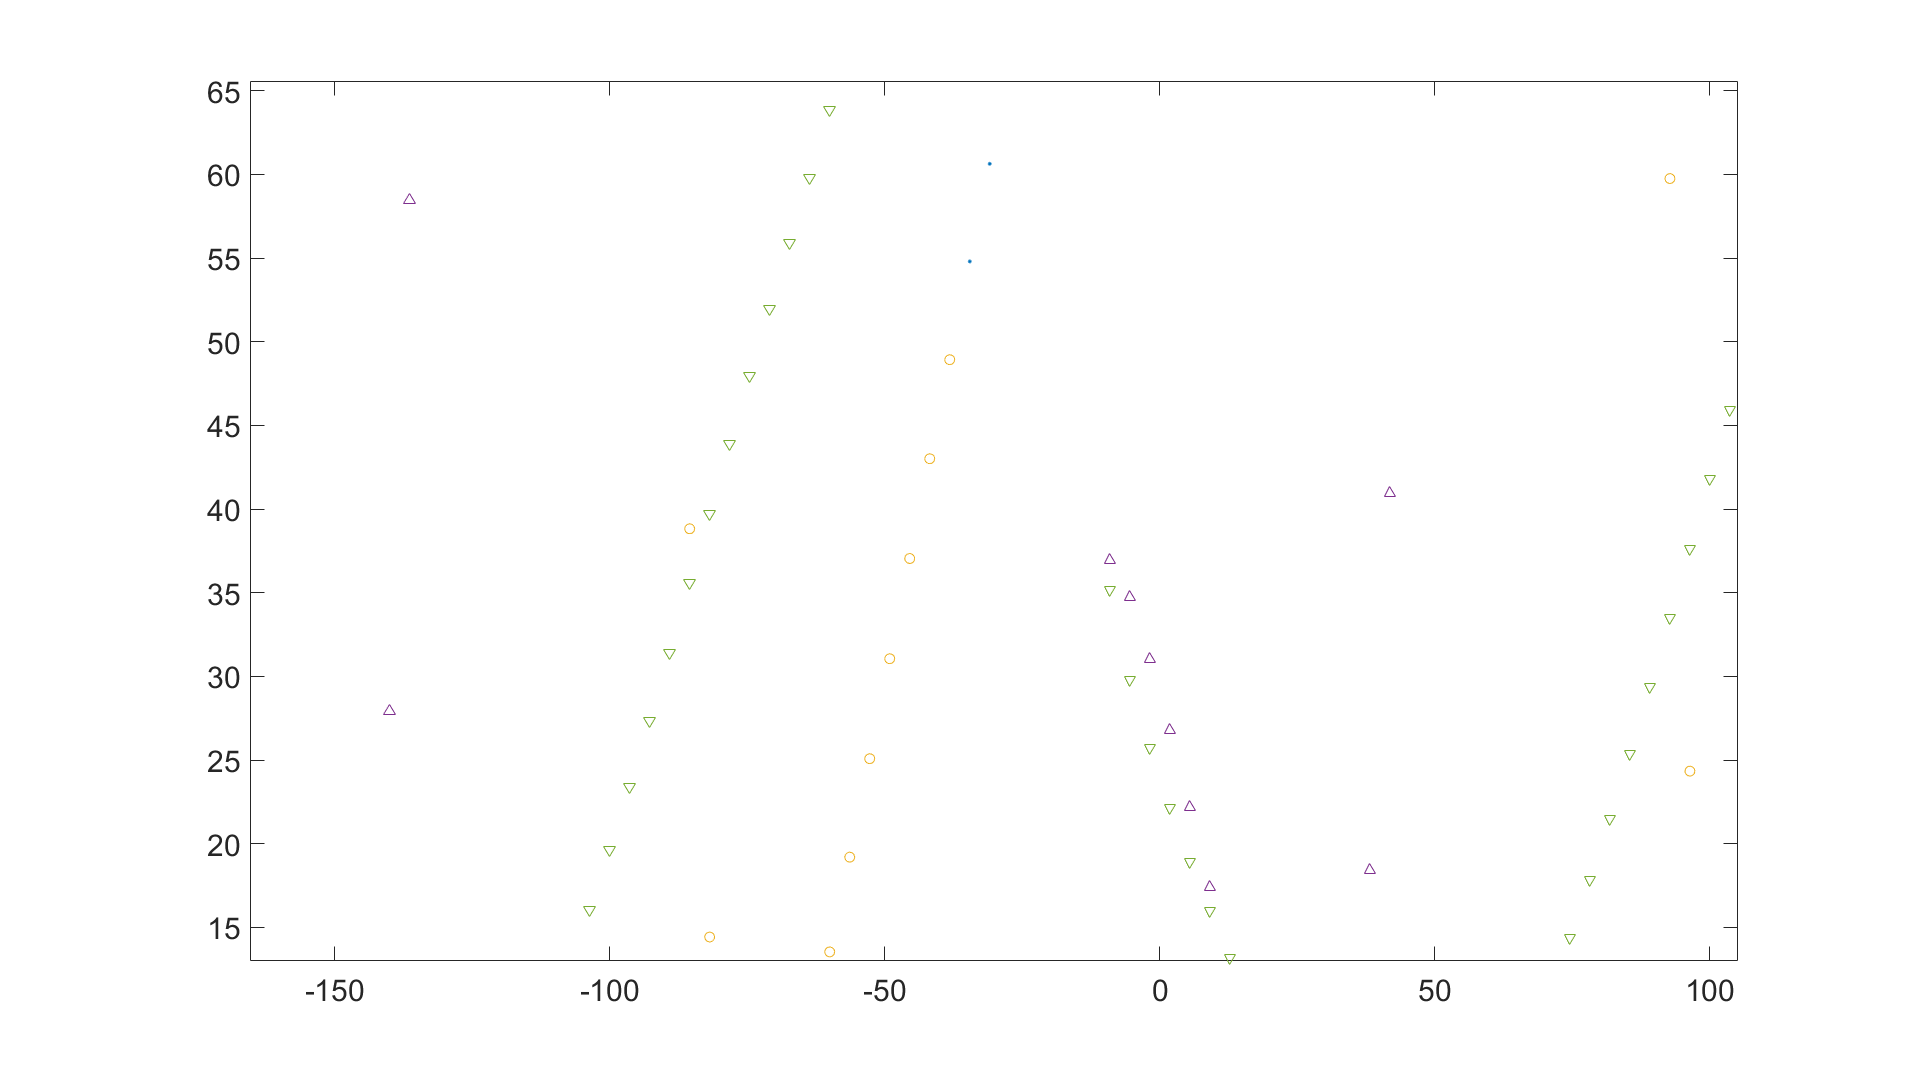

gain(imag(amp_roots) ~=0) = NaN;
gain(amp_roots < 0 ) = NaN;
input_phase = input_phase *180/pi;
figure
plot(input_phase, gain(:,1),'.')
hold on
plot(input_phase, gain(:,2),'x')
plot(input_phase, gain(:,3),'o')
plot(input_phase, gain(:,4),'^')
plot(input_phase, gain(:,5),'v')
axis([min(input_phase) max(input_phase) -0 70])